# TP2 EDP 

clear all;
close all;
clc;

## les données du problème:

% la longueur
Lx=1;
Ly=1;
% nombre de point
Nx=41;
Ny=41;
N=Nx*Ny;
% discritisation d'espace maillage

hx=2*Lx/Nx;
hy=2*Ly/Ny;

% pas de temps 
T=0.1;
Nt=1000;
dt=T/Nt;
% diffusivité thermique
a=1 ;
% amplitude tourbillon = vitesse de diffusion
Um=10; 

## Construction du maillage 

#### linéaire linéaire convection et diffusion

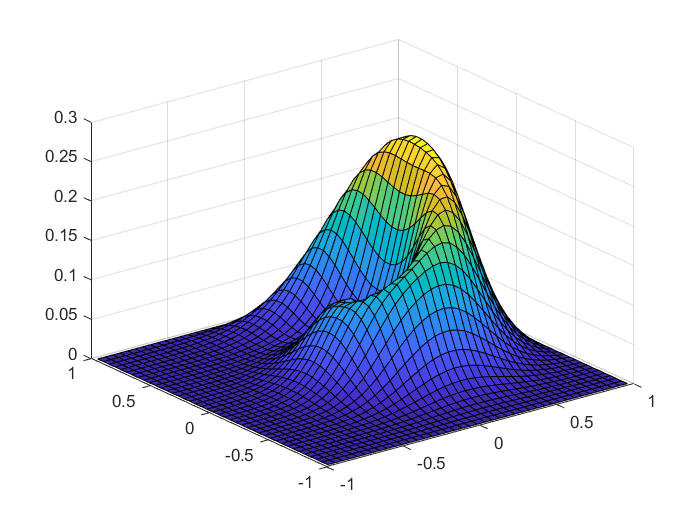

Error using matlab.graphics.axis.Axes/get
Operation terminated by the user.

Error in axis>LocCheckCompatibleLimits (line 252)
v1 = get(axH,[names{1} 'Lim']);

Error in axis (line 113)
                error(LocCheckCompatibleLimits(ax(j)));

A1=zeros(N,N);
A2=zeros(N,N);
for i=1:Nx
    X(i)=-Lx+(i-1/2)*hx;
end
        
for j=1:Ny
    Y(j)=-Ly+(j-1/2)*hy;
end

% terme diffusif
for i=2:Nx-1 
    for j=2:Ny-1
        p=i+(j-1)*Nx;

        A1(p,p)=1+dt*(-2)*a*(1/(hx^2)+1/(hy^2));
        A1(p,p-1)=a*dt/hx^2;    
        A1(p,p+1)=a*dt/hx^2;
        A1(p,p-Nx)=a*dt/hy^2;
        A1(p,p+Nx)=a*dt/hy^2;
      
    end 
end

u=@(x,y,Um) -(Um*y)/(x^2+y^2); 
v=@(x,y,Um) (Um*x)/(x^2+y^2);

% le terme de dispersion:
for i=2:Nx-1 
    for j=2:Ny-1
        p=i+(j-1)*Nx;
        ue = u(X(i)+hx/2,Y(j),Um);
        uw=u(X(i)-hx/2,Y(j),Um);
        vn=v(X(i),Y(j)+hy/2,Um);
        vs=v(X(i),Y(j)-hy/2,Um);

        A2(p,p)=-dt/(2*hx)*(ue-uw)-dt/(2*hy)*(vn-vs);
        A2(p,p-1)=(dt/(2*hx))*uw;   
        A2(p,p+1)=-(dt/(2*hx))*ue;
        A2(p,p-Nx)=(dt/(hy*2))*vs;
        A2(p,p+Nx)=-(dt/(hy*2))*vn;

    end 

end
A=A2+A1;

theta_zero=zeros(N,1);


for i=1:Nx
    for j=1:Ny
        p=i+(j-1)*Nx;
        if (X(i)-Lx/2)^2+Y(j)^2<=(Lx/4)^2         
            theta_zero(p,1)=1;            
        end

    end 
end

theta_prec = theta_zero;
%affichage:

for k=1:Nt
    theta_suiv = A*theta_prec;
    thetam = reshape(theta_suiv,Nx,Ny);
    surf(X,Y,thetam);
    axis([-Lx,Lx,-Ly,Ly,0,1]);    
    theta_prec=theta_suiv;
    pause(0)

end

## linéaire-Upwind:

Aupw=zeros(N,N);
%le therme de convection:
for i=2:Nx-1 
    for j=2:Ny-1
        p=i+(j-1)*Nx;
        ue = u(X(i)+hx/2,Y(j),Um);
        uw=u(X(i)-hx/2,Y(j),Um);
        vn=v(X(i),Y(j)+hy/2,Um);
        vs=v(X(i),Y(j)-hy/2,Um);
        if ue<0
           Aupw(p,p+1)=dt/hx*ue;
        else 
           Aupw(p,p)=dt/hx*ue;  
        end        
        if uw<0
           Aupw(p,p-1)=-dt/hx*uw;
        else 
           Aupw(p,p)=-dt/hx*uw;  
        end
        if vn<0
            Aupw(p,p+Nx)=dt/hx*vn;
        else 
            Aupw(p,p)=dt/hx*vn;  
        end
        if vs<0
            Aupw(p,p-Nx)=-dt/hx*vs;
        else 
            Aupw(p,p)=-dt/hx*vs;  
        end
    end

end

theta_prec = theta_zero;


## affichage:

for k=1:Nt
    theta_suiv = (A1+Aupw)*theta_prec;
    thetam = reshape(theta_suiv,Nx,Ny);
    surf(X,Y,thetam);
    axis([-Lx,Lx,-Ly,Ly,0,1]);    
    theta_prec=theta_suiv;
    pause(0)

end